# Weather actions

GitHub Action to scrape the weather️

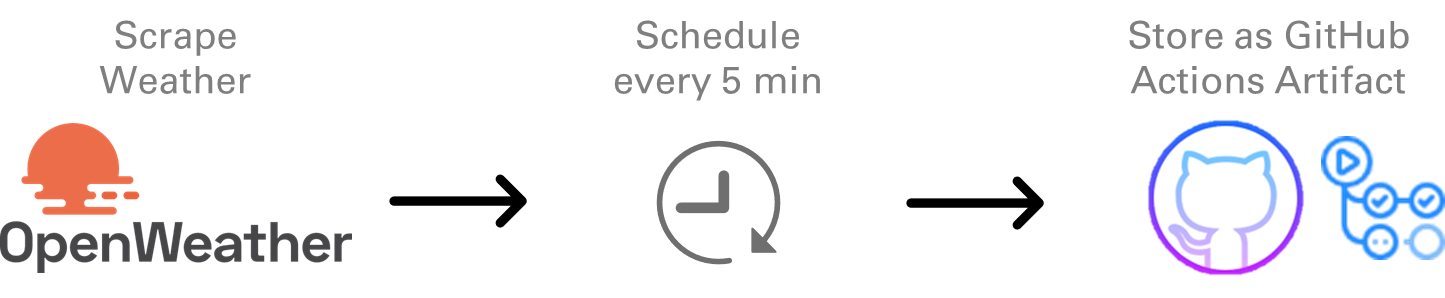

### Intro

GitHub Actions enable to trigger workflows on schedule.

This is the syntax used in order to scrape the weather.

But the precision of the scheduler isn't great, so retiming will be necessary in post-processing.

This script will retrieve Artifacts from GitHub Actions that scraped openweathermap.

### Setup

This setup step is specific to MATLAB Online, retrieving 

if matlab.internal.environment.context.isMATLABOnline
    setup_python
end

Defaulting to user installation because normal site-packages is not writeable
□[?25l   □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □0.0/1.8 MB□ □?□ eta □-:--:--□
□[2K   □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □1.8/1.8 MB□ □84.9 MB/s□ eta □0:00:00□
□[?25hDownloading setuptools-80.9.0-py3-none-any.whl (1.2 MB)
□[?25l   □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □0.0/1.2 MB□ □?□ eta □-:--:--□
□[2K   □━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━━□ □1.2/1.2 MB□ □35.3 MB/s□ eta □0:00:00□
□[?25hDownloading wheel-0.45.1-py3-none-any.whl (72 kB)
□[

Connect to Python in Out-Of-Process execution mode (to enable the termination of the environment without logging out of MATLAB Online)

pe = pyenv(ExecutionMode="OutOfProcess")

pe =   PythonEnvironment with properties:

          Version: "3.10"
       Executable: "/usr/bin/python3"
          Library: "libpython3.10.so.1.0"
             Home: "/usr"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


Create a GitHub [Personal Access Token](https://github.com/settings/personal-access-tokens/new) with permission to the repo actions (read only), and save it as a variable `GITHUB_TOKEN `in  a file called `.env`

loadenv(".env")
token = getenv("GITHUB_TOKEN");

### PyGitHub

g = py.github.Github(token);
repo = g.get_repo("slevin48/weather-scraper")

repo =   Python Repository with properties:

                  allow_auto_merge: [1x1 py.NoneType]
                     allow_forking: 1
                allow_merge_commit: [1x1 py.NoneType]
                allow_rebase_merge: [1x1 py.NoneType]
                allow_squash_merge: [1x1 py.NoneType]
               allow_update_branch: [1x1 py.NoneType]
          anonymous_access_enabled: [1x1 py.NoneType]
                       archive_url: [1x76 py.str]
                          archived: 0
                     assignees_url: [1x70 py.str]
                         blobs_url: [1x69 py.str]
                      branches_url: [1x71 py.str]
                         clone_url: [1x47 py.str]
                   code_of_conduct: [1x1 py.NoneType]
                 collaborators_url: [1x82 py.str]
                      comments_url: [1x71 py.str]
                       commits_url: [1x67 py.str]
          

% repo.get_contents("README.md").decoded_content.decode("utf-8")

Fetch successful workflow runs from the repository

successful_runs = repo.get_workflow_runs(status="success")

successful_runs =   Python PaginatedList with properties:

    is_graphql: 0
       is_rest: 1
      reversed: [1x1 py.github.PaginatedList.PaginatedList]
    totalCount: [1x1 py.int]



Build a list of the names and IDs of the successful runs

runs_list = pyrun("runs_list = [run.id for run in successful_runs]","runs_list",successful_runs=successful_runs)

runs_list =   Python list with values:

    [16391395647, 16391241500, 16391191471, 16390929116, 16390804032, 16390682584, 16390456143, 16390314706, 16390229454, 16390133881, 16389964859, 16389837244, 16389786553, 16389662839, 16389486972, 16389373560, 16389306222, 16389174569, 16388929436, 16388591956, 16388389249, 16388331245, 16388266679, 16388192423, 16388067912, 16387967805, 16387917262, 16387817958, 16387621136, 16387480892, 16387434103, 16387339682, 16387183632, 16387052613, 16386929475, 16386718842, 16386555986, 16386502359, 16386397034, 16386268977, 16386124980, 16386030270, 16385781572, 16385631558, 16385578983, 16385448348, 16385194196, 16385091436, 16384870251, 16384569967, 16383763637, 16383554036, 16383510363]

    Use string, double or cell function to convert to a MATLAB array.


### Artifacts

Python black magic one liner extend/list comprehension (ask ChatGPT)

artifacts_info = pyrun('artifacts_info = [];artifacts_info.extend([{**{"run_id": run_id, "artifact_obj": a}, "artifact_id": a.id, "name": a.name, "size_in_bytes": a.size_in_bytes, "created_at": a.created_at, "expired": a.expired} for run_id in runs_list for a in repo.get_workflow_run(run_id).get_artifacts()])', 'artifacts_info', runs_list=runs_list, repo=repo)

artifacts_info =   Python list with values:

    [{'run_id': 16391395647, 'artifact_obj': Artifact(name="boston-weather", id=3570153600), 'artifact_id': 3570153600, 'name': 'boston-weather', 'size_in_bytes': 550, 'created_at': datetime.datetime(2025, 7, 19, 18, 12, 58, tzinfo=datetime.timezone.utc), 'expired': False}, {'run_id': 16391241500, 'artifact_obj': Artifact(name="boston-weather", id=3570118115), 'artifact_id': 3570118115, 'name': 'boston-weather', 'size_in_bytes': 546, 'created_at': datetime.datetime(2025, 7, 19, 17, 53, 4, tzinfo=datetime.timezone.utc), 'expired': False}, {'run_id': 16391191471, 'artifact_obj': Artifact(name="boston-weather", id=3570107235), 'artifact_id': 3570107235, 'name': 'boston-weather', 'size_in_bytes': 553, 'created_at': datetime.datetime(2025, 7, 19, 17, 46, 42, tzinfo=datetime.timezone.utc), 'expired': False}, {'run_id': 16390929116, 'artifact_obj': Artifact(name="boston-weather", id

a1 = artifacts_info{1}.get('artifact_obj')

a1 =   Python Artifact with properties:

      archive_download_url: [1x86 py.str]
                created_at: [1x1 py.datetime.datetime]
                      etag: [1x68 py.str]
                   expired: 0
                expires_at: [1x1 py.datetime.datetime]
                  head_sha: [1x1 py.NoneType]
                        id: [1x1 py.int]
             last_modified: [1x1 py.NoneType]
    last_modified_datetime: [1x1 py.NoneType]
                      name: [1x14 py.str]
                   node_id: [1x28 py.str]
                  raw_data: [1x1 py.dict]
               raw_headers: [1x1 py.dict]
                 requester: [1x1 py.github.Requester.Requester]
             size_in_bytes: [1x1 py.int]
                updated_at: [1x1 py.datetime.datetime]
                       url: [1x82 py.str]
              workflow_run: [1x1 py.github.WorkflowRun.WorkflowRun]

    Artifact(name="boston-weat

df = pyrunfile("utils.py","df",artifacts_info=artifacts_info);
T = table(df);
T = sortrows(T, "time")

T = 52x9 table
            time            temp     feels_like    temp_min    temp_max    pressure    humidity    sea_level    grnd_level
    ____________________    _____    __________    ________    ________    ________    ________    _________    __________

    19-Jul-2025 01:33:29    69.13      68.94        65.14        71.1        1019         68         1019          1015   
    19-Jul-2025 01:59:16    68.59       68.4         64.2       70.21        1019         69         1019          1015   
    19-Jul-2025 03:38:33     65.5      65.26           61       67.44        1019         75         1019          1016   
    19-Jul-2025 04:16:16    64.94      64.65        60.39      

Plot over time

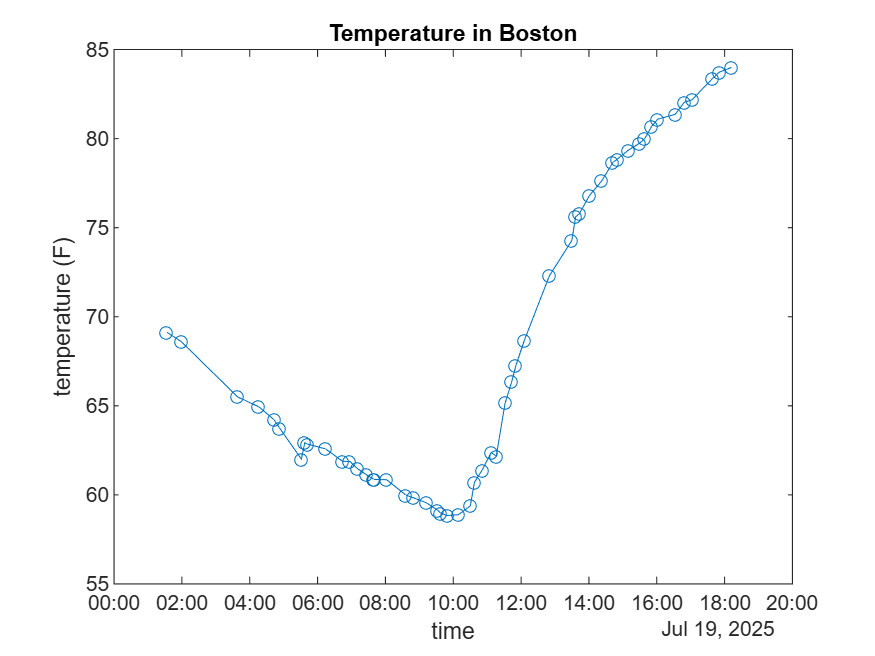

plot(T.time,T.temp,'o-')
xlabel('time')
ylabel('temperature (F)')
title('Temperature in Boston')

### Retime

TT = table2timetable(T);

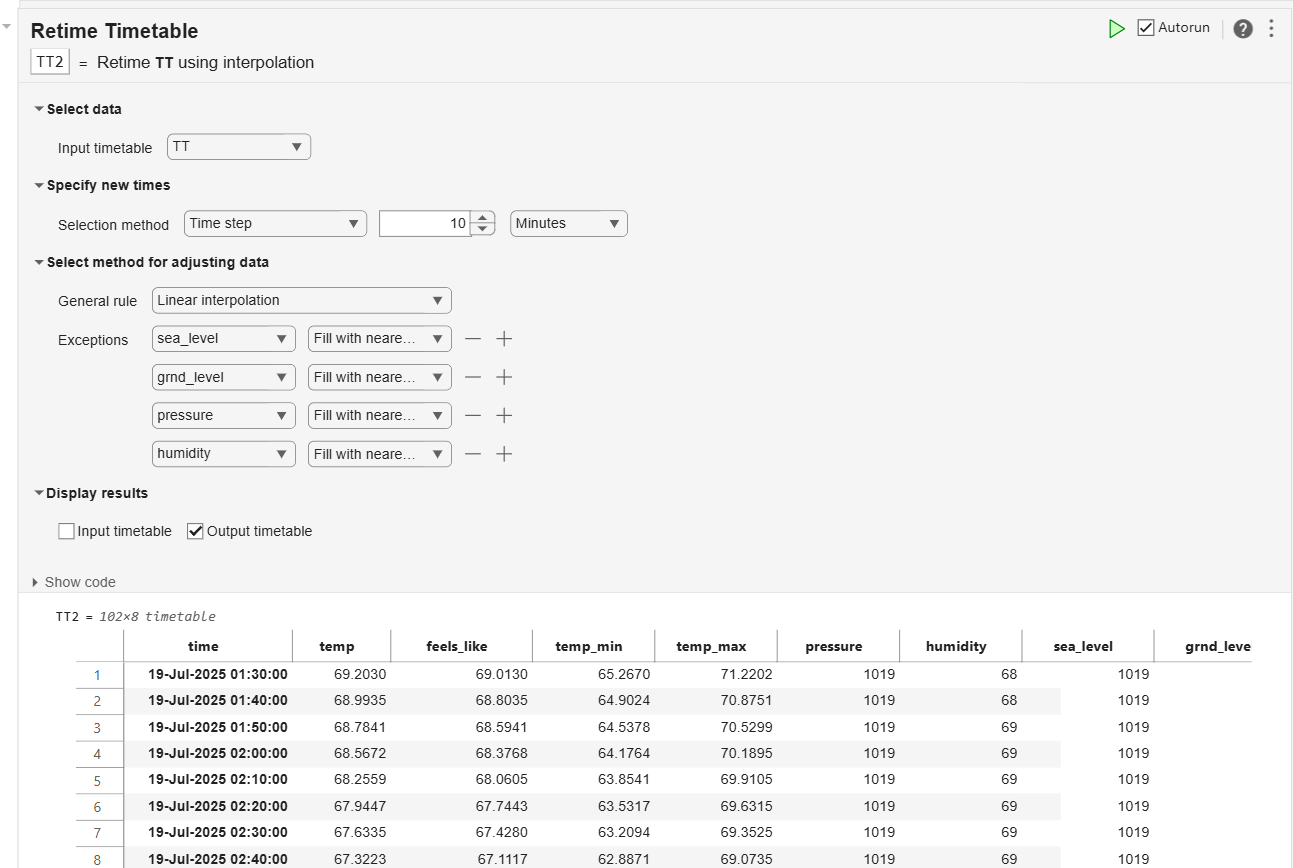

% Retime timetable
TT2 = retime(TT(:,[1 2 3 4]),"regular","linear","TimeStep",minutes(10));

% Retime each override variable to same time vector
temp2.Vars = ["pressure","humidity","sea_level","grnd_level"];
temp2.Methods = ["nearest","nearest","nearest","nearest"];
temp2.Locations = [5 6 7 8];
for k = 1:4
    TT3 = retime(TT(:,temp2.Vars(k)),TT2.Properties.RowTimes, ...
        temp2.Methods(k));
    TT2 = addvars(TT2,TT3.(1),'Before',temp2.Locations(k), ...
        'NewVariableNames',temp2.Vars(k));
end
clear temp2 k TT3

% Display results
TT2

TT2 = 102x8 timetable
            time             temp     feels_like    temp_min    temp_max    pressure    humidity    sea_level    grnd_level
    ____________________    ______    __________    ________    ________    ________    ________    _________    __________

    19-Jul-2025 01:30:00    69.203      69.013       65.267       71.22       1019         68         1019          1015   
    19-Jul-2025 01:40:00    68.994      68.804       64.902      70.875       1019         68         1019          1015   
    19-Jul-2025 01:50:00    68.784      68.594       64.538       70.53       1019         69         1019          1015   


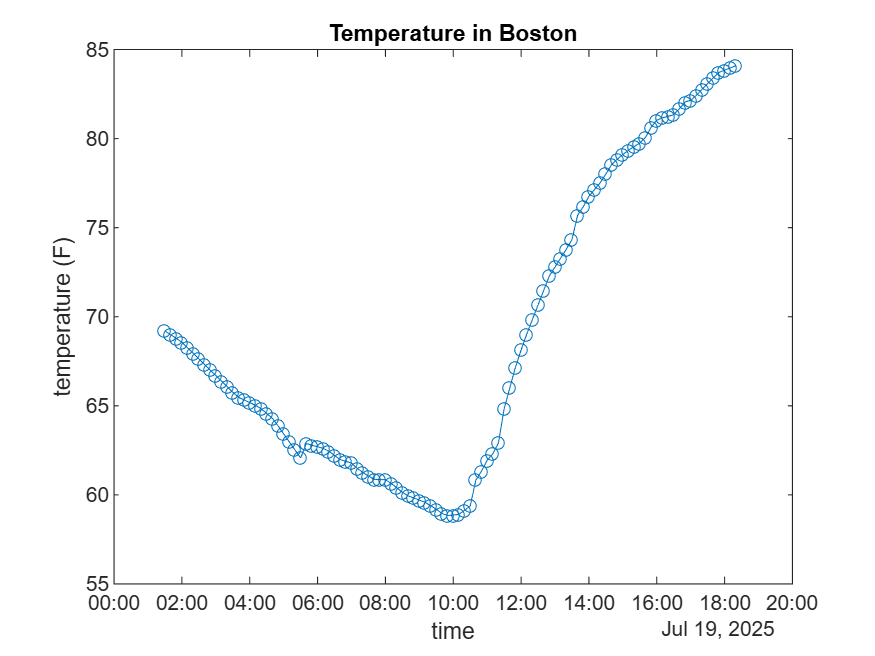

plot(TT2.time,TT2.temp,'o-')
xlabel('time')
ylabel('temperature (F)')
title('Temperature in Boston')

writetimetable(TT2,"boston-retimed.csv")

export weather_actions.mlx README.md;